Implement a program for the visualization of the Armijo line search method in case of R → R functions. Show the effect of the parameters c and ρ, i.e. plot the objective function, the separator line corresponding to c and the points examined by the algorithm. Find some nice test functions and configurations for demonstration.

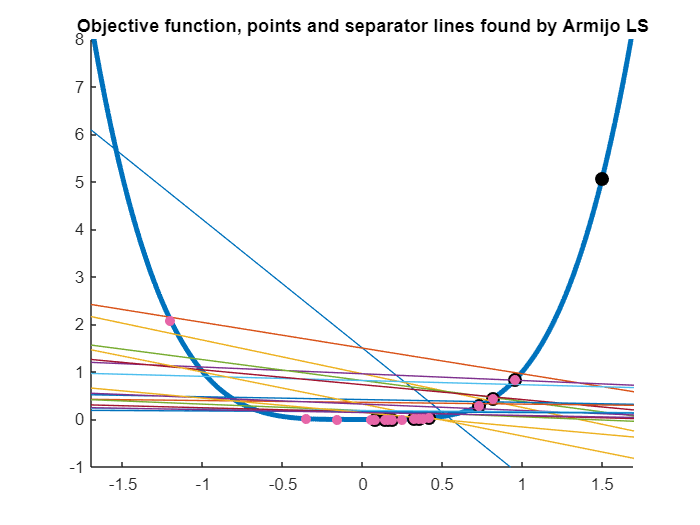

% the pinky dots are points found by algorithm
% the colorful lines are separator lines
clear
f = @(x) x.^4;
df = @(x) 4*x.^3;
ddf = @(x) 12*x.^2;
% we can see the effect of the parameters c and rho, if we change the values
c=0.5; % sufficient decrease condition 
rho=0.2; % step length multiplier

result = test_single_method(@Armijo_LS_R, f, df, ddf, 10, 1.5, -1.7, 1.7, 256,c,rho);

function [x, points_t, lines_t] = Armijo_LS_R(f,df,~,x0,~,~,iter, c, rho)
    alpha = 1; % Initial step length
    
    points_t = [];
    lines_t = [];
    
    x = x0;
    for k = 1:iter
        p = -df(x); 
        % we pass step length and decrease condition to Armijo, Armijo LS examines further points 
        [gamma, points, lines] = Armijo_LS(f, df, p, x, alpha, rho, c); 
        x = x + gamma * p;
        points_t = [points_t; points];
        lines_t = [lines_t; lines];
    end
end

function [alpha, points, lines] = Armijo_LS(f, df, p, x0, alpha, rho, c)
% f: real->real function -- the objective
% df: derivative
% x0: starting point
% This method repeatedly (exactly "iter" times) performs a linesearch on f in the descent direction;
% each iteration runs until the Armijo condition is satisfied for some fixed parameter values.
    f0 = f(x0);
    g0 = df(x0);
    x = x0 + alpha .* p;
    fk = f(x);
    dp = (g0'*p); % direction derivative at x0
    
    points = [];
    lines = [];
    
    % Repeat until the Armijo conditions are satisfied
    while fk < f0 + c * alpha * dp
      alpha = alpha / rho;
      x = x0 + alpha * p;
      fk = f(x);
      
      points = [points; x];
      lines = [lines; x0 alpha*p];
    end
    
    while fk > f0 + c * alpha * dp
      alpha = rho * alpha;
      x = x0 + alpha * p;
      fk = f(x);
      
      points = [points; x];
      lines = [lines; x0 alpha*p];
    end
end